# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 12-Mar-2024 13:55:23

## Load Network Parameters

Load network parameters like weights, biases, or layers unusupported for network code generation from the the stored parameters file.

params = load("C:\Users\PAVAN KUMAR REDDY\OneDrive\Documents\MATLAB\params_2024_03_12__13_55_10.mat");

## Create Array of Layers

layers = [
    imageInputLayer([227 227 3],"Name","data","Mean",params.data.Mean)
    convolution2dLayer([11 11],96,"Name","conv1","BiasLearnRateFactor",2,"Stride",[4 4],"Bias",params.conv1.Bias,"Weights",params.conv1.Weights)
    reluLayer("Name","relu1")
    crossChannelNormalizationLayer(5,"Name","norm1","K",1)
    maxPooling2dLayer([3 3],"Name","pool1","Stride",[2 2])
    groupedConvolution2dLayer([5 5],128,2,"Name","conv2","BiasLearnRateFactor",2,"Padding",[2 2 2 2],"Bias",params.conv2.Bias,"Weights",params.conv2.Weights)
    reluLayer("Name","relu2")
    crossChannelNormalizationLayer(5,"Name","norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2","Stride",[2 2])
    convolution2dLayer([3 3],384,"Name","conv3","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.conv3.Bias,"Weights",params.conv3.Weights)
    reluLayer("Name","relu3")
    groupedConvolution2dLayer([3 3],192,2,"Name","conv4","BiasLearnRateFactor",2,"Padding",[1 1 1 1],"Bias",params.conv4.Bias,"Weights",params.conv4.Weights)
    reluLayer("Name","relu4")
    fullyConnectedLayer(10,"Name","fc")
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(10,"Name","fc_1")
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(10,"Name","fc_2")
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];

## Plot Layers

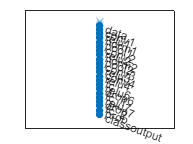

plot(layerGraph(layers));